% Exercicio 1

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

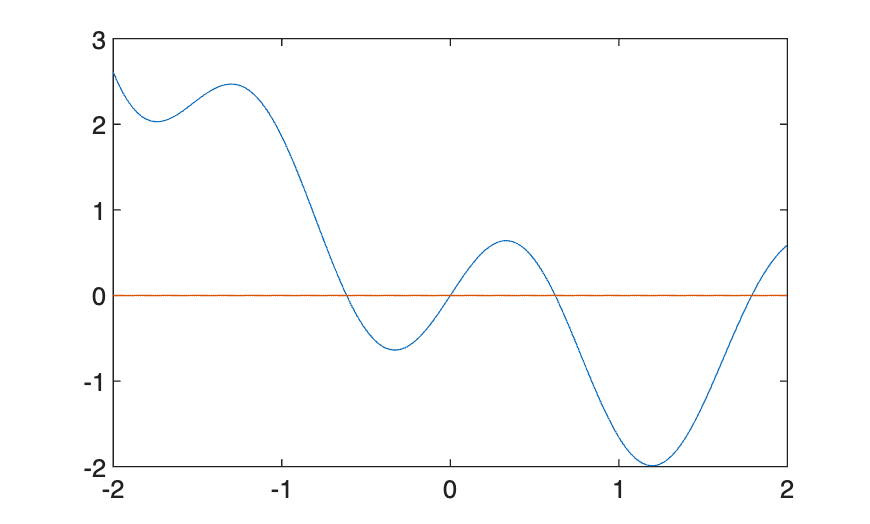

% (a)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% definicao de algumas funcoes uteis
zero = @(x) zeros(size(x));
f = @(x) x.^4/10 + sin(4*x) - x;
dfdx = @(x) 2*(x.^3)/5 + 4*cos(4*x) - 1;
g = @(x) x.^4/10 + sin(4*x); 
dgdx = @(x) 2*(x.^3)/5 + 4*cos(4*x);

% variaveis para o plot
x = linspace(-2,2,1000);
y1 = zero(x);
y2 = f(x);

% plot do grafico
figure;
plot(x, y2);
hold on;
plot(x, y1);
hold off;


% gravar o grafico como um png
% saveas(gcf, 'my_plot.png');

% obtencao dos varios zeros da funcao f
z1 = fzero(f, -0.6);
z2 = fzero(f, 0);
z3 = fzero(f, 0.75);
z4 = fzero(f, 1.75);

% derivada de f nos zeros para verificar atratividade/repulsividade dos pontos fixos de g
dgdx(z1)

ans =   -3.201142634268165


dgdx(z2)

ans =      4


dgdx(z3)

ans =   -3.081653599268148


dgdx(z4)

ans =    4.864193756851231



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% (b)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% metodo de newton x_n+1 = h(x_n) = x_n - f(x_n)/f'(x_n)

% definicao da funcao iterativa
h = @(x) x - f(x) ./ dfdx(x);

% condicoes iniciais
x0 = [-1.2; -0.2; 1.0; 2.0]; % se substituirmos -1.2 por -0.5 ele converge

% a matriz A vai ser a matrix que contem x_i na sua i+1 esima coluna, pois a primeira coluna tem x0
A = x;

% iteracao
for i = 1:5
    x = h(x);
    A = [A, x];
end

x

x = 1.0e+02 *

  -0.004406258090907  -0.030092830362815   0.378427027240006  -0.005285916348598   0.002057424203034  -0.040906134648660  -0.033338903350600  -0.060744252622528  -0.015849478488686  -0.016216070288132  -0.019921956053006  -0.031882670352439  -0.056525606839624  -0.285983173671967   0.069044493544828   0.027628449321559   0.019652458469114   0.017885476372960   0.027778535996683   0.006222476363086   0.006264768637433  -0.000000000001855                   0   0.000000000024763   0.006224870708704  -0.017493747858255  -0.006153092497987  -0.006151777314090  -0.006151727527760  -0.006151726616242  -0.006151726606198  -0.006151726606158  -0.006151726606158  -0.006151726606158  -0.006151726606158  -0.006151726606158  -0.006151726606158  -0.006151726606158  -0.006151726606158  -0.006151726606158  -0.006151726606159  -0.006151726634094  -0.006215454515121   0.006222489725249  -0.000000000021457                   0                   0                   0   0.000000000000000   0.


% erro da ultima iterada relativamente ao zero calculado por fzero
format long
z=[z1; z2; z3; z4];
e = abs(z - A(:, 6))

e =    1.364807319364212
   1.979979979979980
   2.602227613445104
   3.768598276744009



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% (c)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% variacao do metodo de newton x_n+1 = h(x_n) = x_n - f(x_n)/f'(x_0)

% definicao da variacao do metodo de newton
h0 = @(x) x - f(x) ./ dfdx(x0);

% atribuicao de nova variavel para a iteracao e criacao da matriz que vai guardar as varias iteracoes
y = x0;
B = y;

% for loop que calcula as varias iteradas
for i = 1:5
    y = h0(y);
    B = [B, y];
end

% derivada de h0 nos zeros para verificacao de convergencia. se abs(d) < 1 o metodo converge
d = ones(4,1) - dfdx(z)./dfdx(x0)

d =   -2.132366460861490
  -0.681966169780324
  -0.269733714454773
  -1.388253448594179



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% (d)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% experimentacao de varios valores iniciais para o metodo (2)
[x, A] = metodo2eps(10^-8, -0.5)

A =   -0.500000000000000  -0.588962627657474


x =   -0.615172658965318


A =   -0.500000000000000  -0.588962627657474  -0.612903539327565  -0.615152371308431  -0.615172658965318  -0.615172660807370


[x, A] = metodo2eps(10^-8, -0.05)

A =   -0.050000000000000   0.010365498689000


x =      3.592744438978412e-11


A =   -0.050000000000000   0.010365498689000  -0.000079645720980   0.000000000035927                   0


[x, A] = metodo2eps(10^-8, 0.6)

A =    0.600000000000000   0.620786536784351


x =    0.622247633275199


A =    0.600000000000000   0.620786536784351   0.622240261978510   0.622247633275199   0.622247633510433


[x, A] = metodo2eps(10^-8, 1.7)

A =    1.700000000000000   1.793537719988038


x =    1.788618292884627


A =    1.700000000000000   1.793537719988038   1.788481225462150   1.788618197580828   1.788618296777981   1.788618007490509   1.788618296794005   1.788618692822973   1.788618296744884   1.788617646213559   1.788618296728169   1.788618216576093   1.788618296806490   1.788618085489386   1.788618296689657   1.788617996718475   1.788618296735904   1.788618479386717   1.788618296758823   1.788619511693535   1.788618296763774   1.788645371881557   1.788618292884627   1.788618297169007


[x, A] = metodo2eps(10^-8, -1.2)

A =   -1.200000000000000   0.115308017308051


x =   -0.615172660695259


A =   -1.200000000000000   0.115308017308051  -0.409430844980923  -0.550985740130632  -0.604550979210415  -0.614755380659793  -0.615171964596615  -0.615172660611599  -0.615172845653584  -0.615172660602500  -0.615172607678016  -0.615172660618936  -0.615172560301303  -0.615172660625882  -0.615172644992437  -0.615172660695259  -0.615172654248674


[x, A] = metodo2eps(10^-8, -0.2)

A =   -0.200000000000000  -0.469808663418852


x =   -0.615172660664478


A =   -0.200000000000000  -0.469808663418852  -0.578044295053166  -0.610949540709446  -0.615103428597614  -0.615172641404645  -0.615172660667745  -0.615172636723258  -0.615172660603681  -0.615172462964100  -0.615172660609728  -0.615172503580263  -0.615172660628713  -0.615172469088709  -0.615172660620446  -0.615172505607643  -0.615172660621179  -0.615172692779824  -0.615172660651394  -0.615172605338413  -0.615172660621013  -0.615172204539513  -0.615172660617289  -0.615173406221700  -0.615172660616264  -0.615168681722556  -0.615172660552668  -0.615172634964587  -0.615172660664478  -0.615172664143901


[x, A] = metodo2eps(10^-8, 1.0)

A =    1.000000000000000  -0.491668773758577


x =   -0.615172657136652


A =    1.000000000000000  -0.491668773758577  -0.586084114880593  -0.612433550777311  -0.615143202822059  -0.615172657136652  -0.615172660590923


[x, A] = metodo2eps(10^-8, 2.0)

A =    2.000000000000000   1.323552659715597


x =   -0.615172660273769


A =    2.000000000000000   1.323552659715597  -0.914672421703635   0.821673638423095  -0.515468687242732  -0.594063668622683  -0.613646447550447  -0.615163429161974  -0.615172660273769  -0.615172661463609


[x, A] = metodo2eps(10^-8, 10.0)

A =   10.000000000000000   9.999990213442000


x =    0.622247631542273


A =   10.000000000000000   9.999990213442000   9.999980426808524   9.999970640099564   9.999960853315123   9.999951066455200   9.999941279519790   9.999931492508894   9.999921705422512   9.999911918260640   9.999902131023280   9.999892343710428   9.999882556322085   9.999872768858248   9.999862981318914   9.999853193704086   9.999843406013762   9.999833618247937   9.999823830406614   9.999814042489790   9.999804254497462   9.999794466429631   9.999784678286295   9.999774890067453   9.999765101773104   9.999755313403247   9.999745524957879   9.999735736437000   9.999725947840608   9.999716159168704   9.999706370421285   9.999696581598348   9.999686792699896   9.999677003725925   9.999667214676434   9.999657425551421   9.999647636350883   9.999637847074824   9.999628057723241   9.999618268296130   9.999608478793492   9.999598689215327   9.999588899561632   9.999579109832403   9.999569320027645   9.999559530147351   9.999549740191524   9.999539950160161   9.999530160053260   9.99952036987


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% (e)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%\

% definicao de algumas funcoes que serao necessarias para o calculo tanto teorico como experimental
d2fdx2 = @(x) 6/5*x.^2 - 16*sin(4*x);
dhdx = @(x) f(x).*d2fdx2(x)./(dfdx(x).^2);
h1 = @(x) x - f(x)./dfdx(x0);
dh1dx = @(x) 1 - dfdx(x)./dfdx(x0);
Psi = @(x) (x.*g(g(x))-g(x).^2)./(g(g(x))-2*g(x)+x);

% valor exato do zero de f / ponto fixo de g e x0
format long
z1 = fzero(f, -0.6);
x0 = -0.7;


% estimativa para o metodo de newton
[xn] = metodonewton(10^-4, x0); % correr o metodo de newton ate ter |xn-xn1|<epsilon
xn1 = h(xn);
abs(z1 - xn1)./abs(z1 - xn) % estimativa

ans =      0


dhdx(z1) % valor teorico

ans =     -6.621250689240076e-17



% estimativa para o metodo 1
[xn] = metodo1(10^-12, x0); % correr o metodo 1 ate ter |xn-xn1|<epsilon
xn1 = h1(xn);
abs(z1 - xn1)./abs(z1 - xn) % estimativa

ans =    2.130434782608696
   3.353497164461248
   0.306238185255198
   3.595463137996219


dh1dx(z1) % valor teorico

ans =   -2.132366460861490
   3.355393261753615
  -0.306904741480288
   3.596503699261387



% estimativa para o metodo 2
[xn, A] = metodo2k(10, x0); % correr o metodo 2 k vezes

A =   -0.700000000000000


xn1 = Psi(xn);
abs(z1 - xn1)./abs(z1 - xn) % estimativa. dependendo de k a estimativa vai ter valores completamente diferentes.

ans =      1.148046407546103e-06


% o valor teorico foi calculado na alinea anterio e corresponde a Psi'(z1)=0

e = abs(z1*ones(1,11)-A) % erro das iteradas

e =    0.084827339384232   0.062941161051071   0.010290176268330   0.000392611003443   0.000000616274425   0.000000000001931   0.000001130079786   0.000000000004246   0.000000123001785   0.000000000004784   0.000000479852261
